Let us do some basic signal processing.

Firstly, let us get some basic ideas about what we are going to do. Since a computer and thus, MATLAb which runs on it is a digital system, we cannot represent an analog signal accurately in MATLAB.

To represent a signal, we are using a sampled version of the signal. Sampling involves storing the values of a function at particular time intervals.

That is, if x(t) is a signal in continuous time, then we can choose a base time interval T and store all values of x at times ..., -2T, -T, 0, T, 2T,... etc.

Thus we get a sampled version x(nT) of x(t).

More number of samples mean that our representation is closer to the actual signal.

Let us create a value of time values at which we will sample our signal in a vector t. 

Do experiment with these values to observe how things are changing. You can implement everything normally using loops also. But that is slower.

dt = 0.01;       % our sampling period. we will store 
                % values at n*dt
               
% since we have a finite memory, we can store only a 
% finite number of samples. Let us choose the time
% from when we start to observe the signal and till when
% vector t contains all time values from -5s to 5s
% at interval dt

% We subtract dt from 5 in the end, because we want exactly
% total time divided by dt number of samples. (10/dt)

t = -5:dt:5-dt;

Now that we have got a time vector, let us simulate some common signals.

1) sine wave

f = 1;   % Frequency of sine wave 1Hz
x = sin(2*pi*f*t);

To plot these, we will use plot function. plot(xvals, yvals) where xvals is a vector of x values and yvals is a vector of corresponding y values.

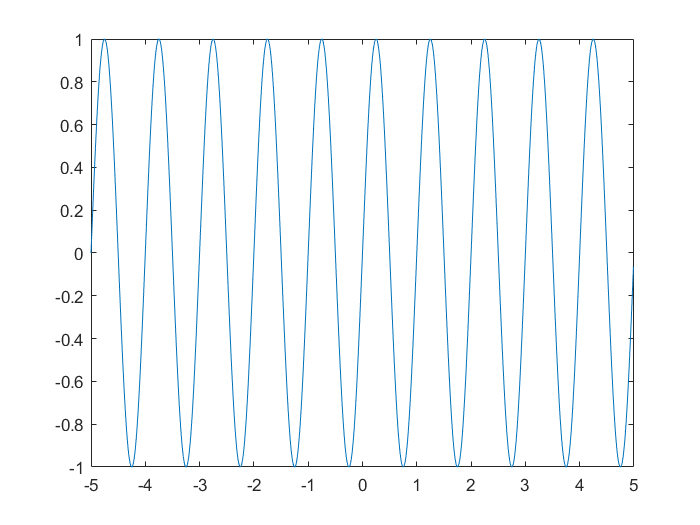

plot(t, x);

2) cosine wave

f = 0.5 % Frequency of cosine wave is half hertz

f = 0.5000

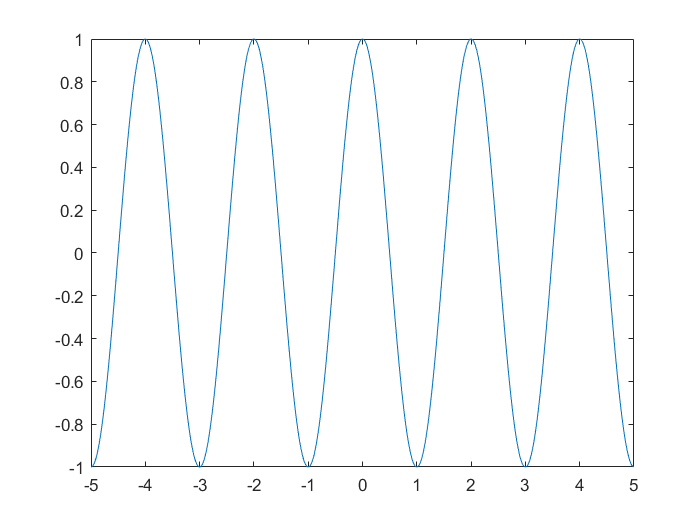

x = cos(2*pi*f*t);
plot(t,x)

3) Unit step function. Unit step function is denoted by u(t). It is 0 for t<0 and 1 for time 0 onwards.

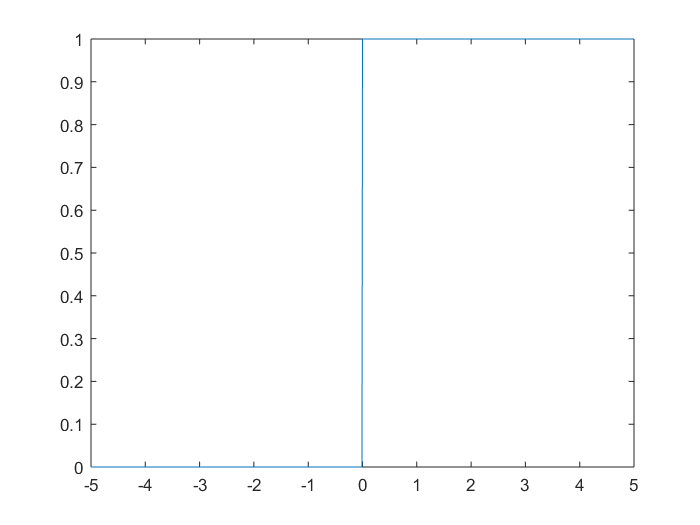

u = t>=0;       % if you are unfamiliar, this performs
                % comparison to 0 with each element ot t
                % and given 1 for true and 0 for false
                % at each position
plot(t, u)

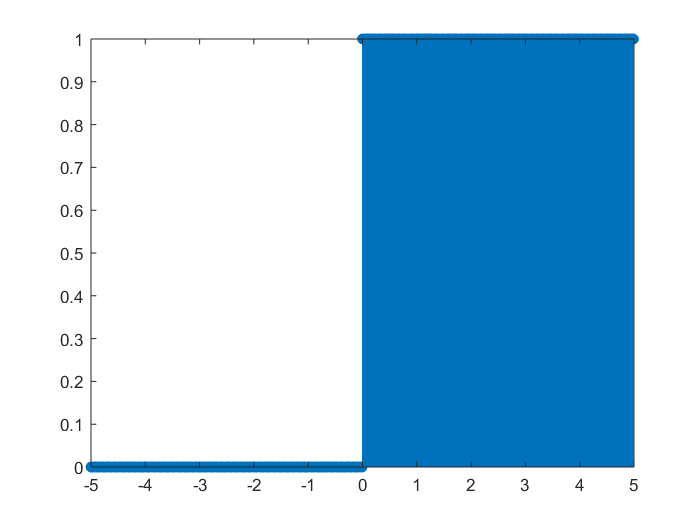

% You can do stem to see better
stem(t, u)

4) Ramp function. It is 0 before t=0 and equal to t after t=0;

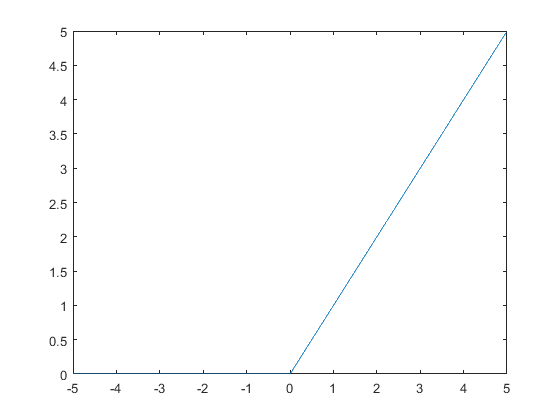

r = t.*u;
plot(t, r);

5) Unit Impulse Function. It is 1 at t=0 and 0 elsewhere

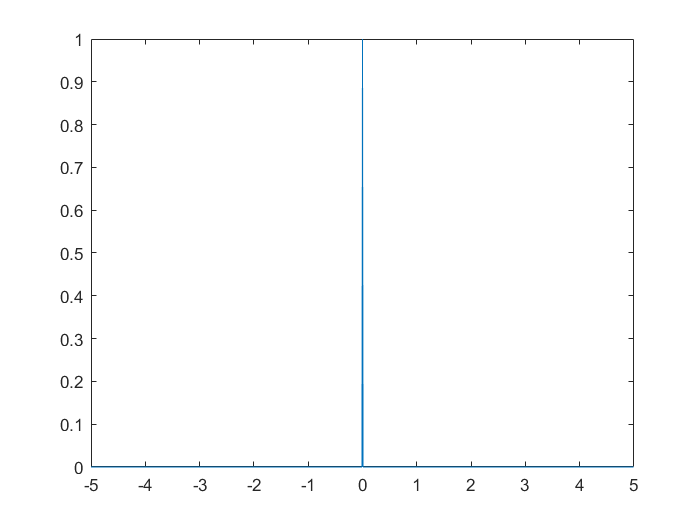

delta = (t==0);
plot(t,delta);

6) Square Wave:

f = 1;           % Frequency 1Hz

f = 1

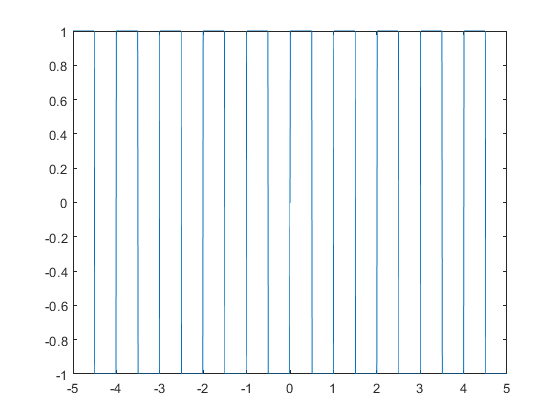

sq = sign(sin(2*pi*f*t));
plot(t, sq);

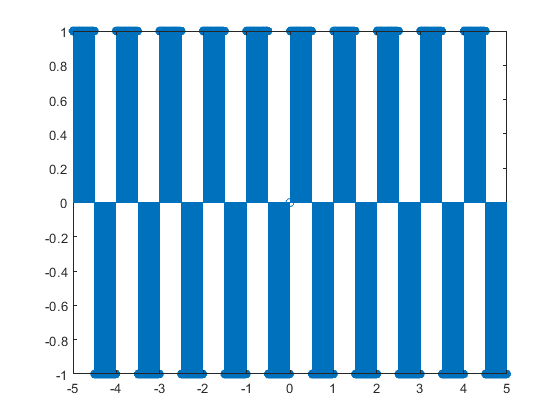

stem(t, sq);

These were some basic signals. In the next document we will see how to deal with digital signals.